# Examine Dual-List Session using Temporal Field Bayes - Time-in-Position Coding

fileDirs = [{'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE11_Session146'},...
    {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE13_Session103'},...
    {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE17_Session110'}];

binSize = 200;
dsRate = 50;
trlWindow = {[-800 2000]};
alignment = {'PokeIn'};
% trlWindow = {[-1500 2000]};
% alignment = {'PokeOut'};
bayesType = 1; %1 = Poisson: use with raw spike counts; 2 = Bernoulli: use with binarized spike counts; 3 = Gaussian: Use with z-scored spike counts

numChancePerms = 100;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);


## Compile DL TIP data

tic;
for ani = 1:length(fileDirs)
    %% Create & setup initial object and data variables (if initial file)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1 
        % Behavior Variables
        fiscPokeOutLat = cell(length(fileDirs),1);
        fiscRwdDelivLat = cell(length(fileDirs),1);
        % Posteriors
        realPost = cell(numel(mlb.odrSeqs), 1, length(fileDirs));
        chancePost = cell(numel(mlb.odrSeqs), 1, length(fileDirs));
    end
    mlb.binSize = binSize;
    mlb.dsRate = dsRate;
    mlb.windows = trlWindow;
    mlb.alignments = alignment;
    mlb.bayesType = bayesType;
    
    %% Extract Behavioral Variables
    if strcmp(alignment{1}, 'PokeIn')
        fiscPokeOutLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeOutIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
        fiscRwdDelivLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).RewardIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    elseif strcmp(alignment{1}, 'PokeOut')
        fiscPokeOutLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeOutIndex])'/1000;
        fiscRwdDelivLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).RewardIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeOutIndex])'/1000;
    end
    %% Process Observations
    % FISC via Leave-1-Out
    mlb.SetLikes_ISC;
    mlb.Process_LikelyL1O;
    tempRealPost = mlb.post;
    %% Process Chance
    fprintf('Processing Chance... ');
    tempPermPost = cell(numel(mlb.odrSeqs),1,numChancePerms);
    for perm = 1:numChancePerms 
        % Re-organize the data if perm ~=1
        if perm ~= 1
            mlb.SetLikes_ISC;
        end        
        mlb.Process_LikelyL1O('Full');
        tempPermPost(:,:,perm) = mlb.post;
    end
    for p = 1:length(mlb.odrVect)
        chancePost{p,1,ani} = tempPermPost{p}(:,:,~isnan(mlb.postTrlIDs(p,:)));
        realPost{p,1,ani} = tempRealPost{p}(:,:,~isnan(mlb.postTrlIDs(p,:)));
    end
    fprintf('\b\bComplete\n');    
end

Compiling StatMatrix Data....Completed


Processing Chance... 

Complete


Compiling StatMatrix Data....Completed


Processing Chance... 

Complete


Compiling StatMatrix Data....Completed


Processing Chance... 

Complete


toc

Elapsed time is 2349.912411 seconds.


## Compile data across animals & compute trial marginals

tic;
likeIDs = cell2mat(mlb.likeTrlIDs(:,:,1));
groupTransMat_PDF = cell(length(mlb.odrVect));
group_Time = cell(length(mlb.odrVect),1);
group_Pos = cell(length(mlb.odrVect),1);
group_Odr = cell(length(mlb.odrVect),1);

chanceTransMat_PDF = cell(length(mlb.odrVect));
chance_Time = cell(length(mlb.odrVect),1);
chance_Pos = cell(length(mlb.odrVect),1);
chance_Odr = cell(length(mlb.odrVect),1);
for p1 = 1:length(mlb.odrVect)
    tempReal = cell2mat(realPost(p1,1,:));
    group_Time{p1} = mlb.TabulateBayesPost(tempReal, likeIDs(:,1));
    group_Pos{p1} = mlb.TabulateBayesPost(tempReal, likeIDs(:,3));
    group_Odr{p1} = mlb.TabulateBayesPost(tempReal, likeIDs(:,4));
    tempChance = cell2mat(chancePost(p1,1,:));
    chance_Time{p1} = mlb.TabulateBayesPost(tempChance, likeIDs(:,1));
    chance_Pos{p1} = mlb.TabulateBayesPost(tempChance, likeIDs(:,3));
    chance_Odr{p1} = mlb.TabulateBayesPost(tempChance, likeIDs(:,4));
    for p2 = 1:length(mlb.odrVect)
        tempOdrLog = likeIDs(:,4)==mlb.odrVect(p2);
        groupTransMat_PDF{p1,p2} = tempReal(:,tempOdrLog,:);
        chanceTransMat_PDF{p1,p2} = tempChance(:,tempOdrLog,:);
    end
end        
toc

Elapsed time is 7.285775 seconds.


## Plot TIP

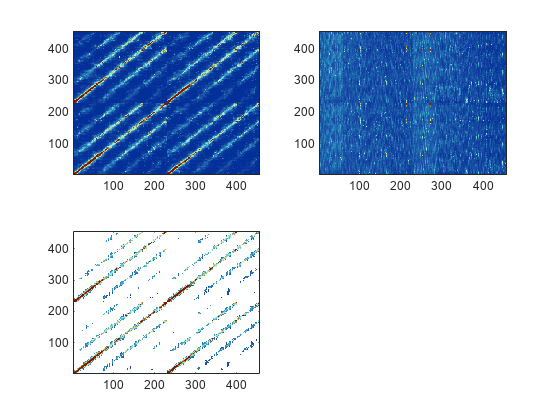

sps = nan(size(mlb.odrSeqs));
figure; 
sps(1) = subplot(2,2,1);
tempRealMean = mean(cell2mat(cellfun(@(a){mean(a,3, 'omitnan')}, realPost)),3, 'omitnan');
imagesc(tempRealMean, postCLim*.5);
set(gca, 'ydir', 'normal');
colormap(sps(1),cMap);

sps(2) = subplot(2,2,2);
tempChanceMean = mean(cell2mat(cellfun(@(a){mean(a,3, 'omitnan')}, chancePost)), 3, 'omitnan');
imagesc(tempChanceMean, postCLim*.5);
set(gca, 'ydir', 'normal');
colormap(sps(2),cMap);

sps(3) = subplot(2,2,3);
sigVals = cell(size(mlb.odrVect));
for odr = 1:length(mlb.odrVect)
    tempSigVal = nan(length(mlb.obsvTimeVect), length(mlb.likeTimeVect));
    tempReal = cell2mat(realPost(odr,:,:));
    tempChance = mean(cell2mat(chancePost(odr,:,:)),3,'omitnan');
    for t1 = 1:length(mlb.obsvTimeVect)
        for t2 = 1:length(mlb.likeTimeVect)
            [~,tempSigVal(t1,t2)] = ttest(tempReal(t1,t2,:), tempChance(odr,t2), 'Tail', 'right');
        end
    end
    sigVals{odr} = tempSigVal;
end
sigVals = cell2mat(sigVals);
[~,q] = mafdr(sigVals(:));
sigLog = reshape(q,size(tempRealMean))<0.05;
tempRealMean(~sigLog) = nan;
imagesc(tempRealMean, postCLim*.5);
set(gca, 'ydir', 'normal');
colormap(sps(3), cMapNanW);
linkaxes(sps(1:3), 'xy');

## Evaluate Dual-List Temporal Coding

## Evaluate Dual-List Ordinal Coding